# CS283 Assignment 3

Enmao Diao, 2017/09/29

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1

## (a)

(i) camera centor$\tilde \bf C$ is known.

In this case we have $ P\mathbf{C} = \mathbf0$. Denote P with row vectors $P =\pmatrix{\mathbf P^{1T}\cr\mathbf P^{2T}\cr\mathbf P^{3T}}$,$\mathbf{C} = (\tilde \mathbf C^T,1)^T=(c_x,c_y,c_z,1)^T = c$, 


$$\pmatrix{\mathbf P^{1T}c\cr\mathbf P^{2T}c\cr\mathbf P^{3T}c} = \mathbf{0}$$


Since $\mathbf{P}^{jT}c_i = c_i ^T\mathbf{P}^{j}$ for $j=1,\cdots,4$


$$(c^T,c^T,c^T)P=(c^T,c^T,c^T)\pmatrix{\mathbf P^{1}\cr\mathbf P^{2}\cr\mathbf P^{3}} =\mathbf{0}$$


from the derivation of $\mathbf{x}\times\mathbf{PX} = \mathbf{0}$, $\mathbf{x}_i = (x_i, y_i , w_i )^T$, we have


$$\pmatrix{  \mathbf{0}^T&-w_i\mathbf{X}_i^T&y_i\mathbf{X}_i^T\cr w_i\mathbf{X}_i^T &\mathbf{0}^T&-x_i\mathbf{X}_i^T\cr -y_i\mathbf{X}_i^&x_i\mathbf{X}_i^T&\mathbf{0}^T\cr }\pmatrix{\mathbf P^{1}\cr\mathbf P^{2}\cr\mathbf P^{3}} = \mathbf{0}$$


Since only three  equations are linearly dependent , we choose the first two and accompany with our derivation we have


$$\pmatrix{\mathbf{0}^T&-w_i\mathbf{X}_i^T&y_i\mathbf{X}_i^T\cr w_i\mathbf{X}_i^T &\mathbf{0}^T&-x_i\mathbf{X}_i^T \cr  c^T&c^T&c^T}\pmatrix{\mathbf P^{1}\cr\mathbf P^{2}\cr\mathbf P^{3}} = \mathbf{0}$$



$$\mathbf{A}p = \mathbf{0}$$


for n corresponding points we have totally $(2n + 1)$ linear constraints in $\mathbf{A}p = \mathbf{0}$

Given the minimum number of correspondences, the solution is exact.The solution is obtained by solving $\mathbf{A}p = \mathbf{0}$**, **where A is an $(2n + 1)$ *× *12 matrix in this case.

(ii)

Since we know$\mathbf{PX} = \mathbf{ KR}[\mathbf{I} | -\mathbf{C} ]\mathbf{X}   = \mathbf{x} $ and we know $\mathbf{R}$ and $\mathbf{C}$ in this case.

Therefore, we can compute $\mathbf{R}[\mathbf{I} | -\mathbf{C}]\mathbf{X} $first and the result is a (3x1) 1 dimensional column vector, and we denote it as $\mathbf{Z}$

The new equation $\mathbf{KZ} = \mathbf{x}$ is in fact similar to 2D homography transfomation, we can use method like in 4.1 to solve this problem


$$\mathbf{x}\times\mathbf{KZ} = \mathbf{0}$$



$$\pmatrix{  \mathbf{0}^T&-w_i\mathbf{Z}_i^T&y_i\mathbf{Z}_i^T\cr w_i\mathbf{Z}_i^T &\mathbf{0}^T&-x_i\mathbf{Z}_i^T\cr -y_i\mathbf{Z}_i^&x_i\mathbf{Z}_i^T&\mathbf{0}^T\cr }\pmatrix{\mathbf K^{1}\cr\mathbf K^{2}\cr\mathbf K^{3}} = \mathbf{0}$$


Since only three  equations are linearly dependent , we choose the first two


$$\pmatrix{  \mathbf{0}^T&-w_i\mathbf{Z}_i^T&y_i\mathbf{Z}_i^T\cr w_i\mathbf{Z}_i^T &\mathbf{0}^T&-x_i\mathbf{Z}_i^T}\pmatrix{\mathbf K^{1}\cr\mathbf K^{2}\cr\mathbf K^{3}} = \mathbf{0}$$



$$\mathbf{A}k = \mathbf{0}$$


for n corresponding points we have totally $2n$ linear constraints in $\mathbf{A}k = \mathbf{0}$

Given the minimum number of correspondences, the solution is exact.The solution is obtained by solving $\mathbf{A}k = \mathbf{0}$**, **where A is an $2n$ *× 9* matrix in this case. 

## (b)

(i)

Since totally there are 11 dof for $\mathbf{P}$ and $(2n + 1)$ linear constraints for n correspondence, we need 5 such correspondences to retrieve the exact solution. In this case, matrix $\mathbf{A}$ is (11x12) with rank(11).

(ii)

Since totally there are 5 dof for $\mathbf{K}$ and $2n$ linear constraints for n correspondence, we need $2\frac{1}{2}$ such correspondences to retrieve the exact solution. In this case, matrix $\mathbf{A}$ is (5x12) with rank(5) and only one of the equations is used from the 3rd point .

# Question 2

we denote points in $\mathbf{I_0}$,$\mathbf{I_1}$ as $\mathbf{x_0}$,$\mathbf{x_1}$, and the world points as $\mathbf{X}$.

First, we take a picture of X and thus we have $\mathbf{P_0X} = \mathbf{x_0}$ and we can normalize $\mathbf{x_0}$ with its 3rd coordinates such that $\mathbf{x_0} = (x_0,y_0,1)^T$. If we wanna retake a picture, then we constrcut homogeneous coordinates of $\mathbf{x_0}$ as $\mathbf{X_0} = (\mathbf{x_0}^T,1)^T$

the new picture we take is $\mathbf{P_1X_0} = \mathbf{x_1}$.

The equivalent operation can be viewed as follows:


$$\pmatrix{p_{11}&p_{12}&p_{13}&p_{14}\cr p_{21}&p_{22}&p_{23}&p_{24}\cr p_{31}&p_{32}&p_{33}&p_{34}\cr}\pmatrix{x_0\cr y_0\cr1\cr 1}$$



$$=\pmatrix{p_{11}&p_{12}&p_{13}+p_{14}\cr p_{21}&p_{22}&p_{23}+p_{24}\cr p_{31}&p_{32}&p_{33}+p_{34}\cr}\pmatrix{x_0\cr y_0\cr1} = \pmatrix{x_1\cr y_1\cr1}$$



$$\mathbf{Hx_0} = \mathbf{x_1}$$


$\mathbf{H}$is a homography transformation. It means that taking a picture of a picture is equivalent to do homography transformation on a picture.


$$\mathbf{HP_0X} = \mathbf{x_1}$$


Then the camera matrix of $\mathbf{X}$ to $\mathbf{x_1}$ is $\mathbf{P}' =\mathbf{HP_0}$. Since $\mathbf{H}$ is invertible, $\mathbf{HP_0C} = \mathbf{0}$ if and only if $\mathbf{P_0C} = \mathbf{0}$. Then since $\mathbf{C}$ is the camera center of $\mathbf{I_0}$, it is also the apparent camera center of $\mathbf{I}'$.

And also since $\mathbf{H}$ is invertible, and $\mathbf{HP_0}$ can be written into $\mathbf{M}[\mathbf{I} | −\tilde \mathbf{C} ] =[\mathbf{M} | −\mathbf{M}\tilde \mathbf{C} ] $ and $\mathbf{M}$is the 3x3 submatrix which can be factorized with QR decompostion into $\mathbf{M} = \mathbf{K}'\mathbf{R}' $

Since we can also write $\mathbf{P_0}$ as $\mathbf{KR}[\mathbf{I} | −\tilde \mathbf{C} ]$ and $\mathbf{M} = \mathbf{KR}$. Obviously, $\mathbf{M}$is not neccessarily equal to $\mathbf{M}'$.

As for a portrait, the painters use shadow and lines to create illusion of depth and thus in our mind we view the picture in 2D plane as in 3D. As long as our eyes stare at the eyes of portraits (i.e taking a picture of the same picture), the camera center (i.e. our eyes in the world coordinates) remains the same no matter where we walk in the room (i.e. the eyes of portraits follow you in the room).

# Question 3

## (a)

See function `getCamera()` below. We first normalize 2D and 3D points based previous homework and then use DLT to retrieve the Over-determined solution.  After denormalization, we have the camera matrix $\mathbf{P}$ 

## (b)

We use the function written in part (a) to estimate camera matrix of two cameras mapping from corner3D porints to their 2D image points.

% add your code here
load('./data/corners.mat');
Pl = getCamera(corners_3D,leftpts);
Pr = getCamera(corners_3D,rightpts);

## (c)

For the camera center $\mathbf{C}$, we use the analytical method written in getC(). The result is the same as numerically computing with svd to find the 1d null vector.

For the orientation matrix $\mathbf{R}$, we can factorize 3x3 submatrix $\mathbf{M}$into $\mathbf{KR}$ with QR decompostion. We also use back projection to show the orientation and field of view of these two cameras. Back-projection of points to rays can be formed by the join of these two points $\mathbf{X}( \lambda) = P^+\mathbf{x} + \lambda\mathbf{C}$*.*  The other points we choose as the corner coordinates of the image. Then we experiment with $\lambda$ and we find appropriate values of $\lambda$ to determine the shape of pentahedron and draw the field of view.

Cl = getC(Pl) % get camera center 

Cl =     0.5283
   -1.3578
    6.2343
    1.0000


tmp_Cl = Cl(1:end-1)';
Cr = getC(Pr)

Cr =     0.3824
    1.7656
    7.7977
    1.0000


tmp_Cr = Cr(1:end-1)';
iml = imread('./data/calib_left.bmp');
imr = imread('./data/calib_right.bmp');
corners_l = getcorners(iml);% get the corner coordinates of left and right image
corners_r = getcorners(imr);
[Kl,Rl] = getKR(Pl);% get KR from QR decomposition, just for shown 
[Kr,Rr] = getKR(Pr);
Rl

Rl =    -0.0148    0.9999   -0.0002
   -0.9999   -0.0148   -0.0002
   -0.0002    0.0002    1.0000


Rr

Rr =    -0.3179    0.9481    0.0002
   -0.9481   -0.3179   -0.0001
   -0.0001   -0.0002    1.0000


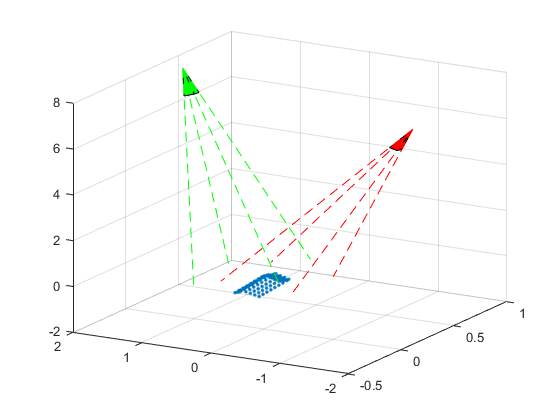

ray_poly_l = pinv(Pl)*corners_l+10*repmat(Cl,1,size(corners_l,2)); % compute the vertices for the pentahedron by appropriately choosing lambda
ray_poly_l = ray_poly_l(1:end-1,:)./repmat(ray_poly_l(end,:),size(corners_l,1),1);
ray_poly_l = ray_poly_l';
ray_poly_r = pinv(Pr)*corners_r-10*repmat(Cr,1,size(corners_r,2));
ray_poly_r = ray_poly_r(1:end-1,:)./repmat(ray_poly_r(end,:),size(corners_r,1),1);
ray_poly_r = ray_poly_r';

ray_poly_l_line = pinv(Pl)*corners_l+0.1*repmat(Cl,1,size(corners_l,2));% compute the end point for line of field of view by appropriately choosing lambda
ray_poly_l_line = ray_poly_l_line(1:end-1,:)./repmat(ray_poly_l_line(end,:),size(corners_l,1),1);
ray_poly_r_line = pinv(Pr)*corners_r-0.1*repmat(Cr,1,size(corners_r,2));
ray_poly_r_line = ray_poly_r_line(1:end-1,:)./repmat(ray_poly_r_line(end,:),size(corners_r,1),1);
figure;
hold on
grid on
view(-60,20)
plotpenta(ray_poly_l,tmp_Cl,'r')
plotpenta(ray_poly_r,tmp_Cr,'g')
plot3([repmat(tmp_Cl(1),1,4);ray_poly_l_line(1,:)],[repmat(tmp_Cl(2),1,4);ray_poly_l_line(2,:)],[repmat(tmp_Cl(3),1,4);ray_poly_l_line(3,:)],'r--')
plot3([repmat(tmp_Cr(1),1,4);ray_poly_r_line(1,:)],[repmat(tmp_Cr(2),1,4);ray_poly_r_line(2,:)],[repmat(tmp_Cr(3),1,4);ray_poly_r_line(3,:)],'g--')
scatter3(corners_3D(:,1),corners_3D(:,2),corners_3D(:,3),'.')

# Question 4

## (a)

As $\mathbf{x} \times\mathbf{PX} = 0$, we want to solve for $\mathbf{X}$. From the textbook we know that for $P =\pmatrix{\mathbf P^{1T}\cr\mathbf P^{2T}\cr\mathbf P^{3T}}$, $\mathbf{x}_i = (x_i, y_i , w_i )^T$


$$\mathbf{x} \times\mathbf{PX} = \pmatrix{y_i\mathbf{P}^{3T}-w_i\mathbf{P}^{2T}\cr w_i\mathbf{P}^{1T}-x_i\mathbf{P}^{3T}\cr x_i\mathbf{P}^{2T}-y_i\mathbf{P}^{1T} }\mathbf{X} = \mathbf{0}$$


Thus for each point correspondence we have three linear constraints. However, since there are only two linearly independent constraints. And we have totally 4 dof for determining $\mathbf{X}$. Thus we need two other constraints from another point correspondence. We can solve $\mathbf{AX} = \mathbf{0} $ with SVD.


$$\mathbf{A} = \pmatrix{y_i\mathbf{P}^{3T}-w_i\mathbf{P}^{2T}\cr w_i\mathbf{P}^{1T}-x_i\mathbf{P}^{3T}\cr y_i'\mathbf{P}^{'3T}-w_i'\mathbf{P}^{'2T}\cr w_i'\mathbf{P}^{'1T}-x_i'\mathbf{P}^{'3T}}$$


## (b)

See function triangulate`()` below.

follow part (a) to implement and solve $\mathbf{AX} = \mathbf{0} $ with SVD

## (c)

Your text and code here.

For each of these seven correspondences, we estimate the world coordinates of the corresponding 3D points through triangulation as mentioned above. We compute the corner coordiatntes for the hidden vertex. With parallelsim,  we first compute the coordinate difference between two points that lie in a line that is parallel to the line that the hidden vertex stands. Then we modify the other point on the same line by the difference accordingly.

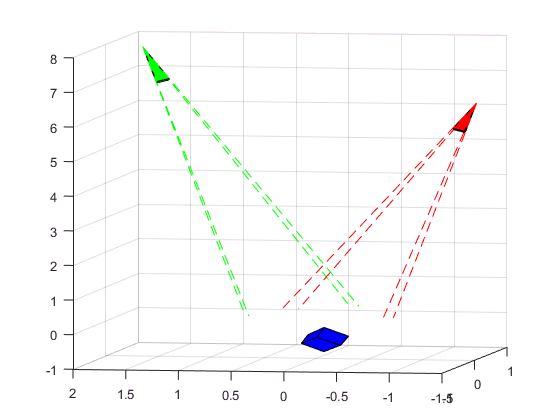

iml = imread('./data/kleenex_left.bmp');
imr = imread('./data/kleenex_right.bmp');
% figure;
% imshow(imr,[]);
% impixelinfo;
x1 = [198 327;203 191;363 270;343 399;422 286;443 163;294 95]; % manually noted corner coordinates
x2 = [220 337;143 225;241 273;319 382;408 278;341 163;241 125];
xl = [x1 ones(size(x1,1),1)];
xr = [x2 ones(size(x2,1),1)];
X = triangulate(xl,xr,Pl,Pr);
figure;
hold on
grid on
view(-80,5)
plotpenta(ray_poly_l,tmp_Cl,'r')
plotpenta(ray_poly_r,tmp_Cr,'g')
plot3([repmat(tmp_Cl(1),1,4);ray_poly_l_line(1,:)],[repmat(tmp_Cl(2),1,4);ray_poly_l_line(2,:)],[repmat(tmp_Cl(3),1,4);ray_poly_l_line(3,:)],'r--')
plot3([repmat(tmp_Cr(1),1,4);ray_poly_r_line(1,:)],[repmat(tmp_Cr(2),1,4);ray_poly_r_line(2,:)],[repmat(tmp_Cr(3),1,4);ray_poly_r_line(3,:)],'g--')
plotcube(X,'b')

## (d)

Your text and equations here.

Since we know the world coordinates and length of the checkboard. We can easily compute the distance between two points in world coordinate system. Then since we also know the world coordinate of ther vertices of kleenex box, we can easily compute the side length and volume of this box.


$$V = a^3 = (d_{cube}\frac{2cm}{d_{check}})^3$$


dist_check = norm([corners_3D(1,:)-corners_3D(2,:)]);
dist_cube = norm([X(1,:)-X(2,:)]);
dist_cube_cm = dist_cube/dist_check*2;
volume = dist_cube_cm^3 % in cm^3

volume = 1.2167e+03

# Bonus Question

Your text and code here.

# Local Functions

function P = getCamera(X3, X2)
    % Problem 3(a)
    % the function that computes the 3x4 camera matrix P from nx3
    % world coordinates X3 and an nx2 matrix of pixel coordinates X2
    % representing the projection of the world points into a single 
    % projective camera
    % replace the next line with your own code
    % check input
    if ((~ismatrix(X3)) || (~ismatrix(X2)) || (size(X3, 1) == 0) || (size(X3, 1) == 0))
        error('Input incorrect.');
    end
    N = size(X3,1);
    c1 = size(X3,2);
    c2 = size(X2,2);
    T1 = getT(X3,c1);
    T2 = getT(X2,c2);
    X3n = (T1*[X3'; ones(1,N)])';
    X2n = (T2*[X2'; ones(1,N)])';
    wixi = repmat(X2n(:,3),1,c1+1).* X3n;
    yixi = repmat(X2n(:,2),1,c1+1).* X3n;
    xixi = repmat(X2n(:,1),1,c1+1).* X3n;
    A = [zeros(N,c1+1),-wixi,yixi;wixi,zeros(N,c1+1),-xixi];
    [~,~,V] = svd(A);
    V_last = V(:,end);
    P_tilde = reshape(V_last,c1+1,c2+1)';
    % replace the next line with your own code
    P = inv(T2)*P_tilde*T1;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% optional functions for problem 3(c)
function T = getT(X,c)
% check input
if ((~ismatrix(X)) || (size(X, 2) ~= c) || (size(X, 1) == 0))
	error('Input incorrect.');
end
N = size(X,1);
mu = mean(X,1);
tmp = [];
for i=1:c
   tmp = [tmp X(:,i)-mu(i)];
end
stdev = norm(tmp);
if stdev > 0
    s = sqrt(c) / stdev;
else
    s = 1;
end
t = zeros(c,1);
for i=1:c
    t(i) = - s * mu(i);
end
% replace the next line with your own code
T = [s*eye(c) t;[zeros(1,c) 1]];
end % end function getT

function C = getC(P)
x = det([P(:,2) P(:,3) P(:,4)]);
y = - det([P(:,1) P(:,3) P(:,4)]);
z = det([P(:,1) P(:,2) P(:,4)]);
t = - det([P(:,1) P(:,2) P(:,3)]);
C = [x/t;y/t;z/t;1];
% [~,~,V] = svd(P);
% C2 = V(:,end);
% C2 = C2./C2(4);
end % end function getC

function [K,R] = getKR(P)
M = P(:,1:3);
[R,K] = qr(M);
end % end function getC

function corners = getcorners(im)
[m,n,~]=size(im);
corners = [1,1,1;1,m,1;n,m,1;n,1,1]';
end % end function getC

function [] = plotpenta(coor,C,color)
patch(coor(:,1),coor(:,2),coor(:,3),color)
vertices = [coor;C];
faces = [1 2 5;2 3 5; 3 4 5;4 1 5];
patch('Faces',faces,'Vertices',vertices,'FaceColor',color)
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function X = triangulate(x1, x2, P1, P2)
    % Problem 4(b)
    % write a function that takes camera matrix P1 and P2, and image
    % points x1, x2 and estimates the 3D world points X 
N = size(x1,1);
c1 = size(P1,1);
X = zeros(N,c1);
for i=1:N
    wih2 = repmat(x1(i,3),1,c1+1).* P1(2,:);
    yih3 = repmat(x1(i,2),1,c1+1).* P1(3,:);
    wih1 = repmat(x1(i,3),1,c1+1).* P1(1,:);
    xih3 = repmat(x1(i,1),1,c1+1).* P1(3,:);
    xih2 = repmat(x1(i,1),1,c1+1).* P1(2,:);
    yih1 = repmat(x1(i,2),1,c1+1).* P1(1,:);
    A1 = [yih3-wih2;wih1-xih3];
    c2 = size(P2,1);
    wih2 = repmat(x2(i,3),1,c2+1).* P2(2,:);
    yih3 = repmat(x2(i,2),1,c2+1).* P2(3,:);
    wih1 = repmat(x2(i,3),1,c2+1).* P2(1,:);
    xih3 = repmat(x2(i,1),1,c2+1).* P2(3,:);
    xih2 = repmat(x2(i,1),1,c1+1).* P2(2,:);
    yih1 = repmat(x2(i,2),1,c1+1).* P2(1,:);
    A2 = [yih3-wih2;wih1-xih3];
    A = [A1;A2];
    [~,~,V] = svd(A);
    V_last = V(:,end);
    V_last = V_last./(V_last(end));
    X(i,:) = V_last(1:end-1);
end
unseen = X(end,:)-(X(2,:)-X(1,:)); % compute unseen coordinates
X = [X; unseen];
end

function [] = plotcube(coor,color)
vertices = coor;
faces = [1 2 3 4;3 4 5 6;6 7 2 3;1 4 5 8;5 6 7 8;7 8 1 2];
patch('Faces',faces,'Vertices',vertices,'FaceColor',color)
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% optional functions for bonus questions

